# Experiment 4

# Bit error rate of Quadrature Phase Shift Keying (QPSK)

# (with and without Gray labelling) in 

# Additive White Gaussian Noise (AWGN)

## Communications Lab

## *190020039*

### Initialize Matlab

close all;
clear;
clc;

### Declaring some variables

% generate QPSK constellation as complex numbers
qpskcon = exp(1i*(2*pi.*(0:3)/4+pi/4));
% SNR array varying in the range of -10 to +10 dB in steps of 1 dB
snrdb=-10:10;
%no of elements in SNR array
nsnrdb = length(snrdb);

### Message signal (bits)

% no of symbols in mesaage array
nsym=50000;
% message bit array
m=randi([0,1],nsym,1);

### QPSK Modulation (without Gray labelling)

% modulating message symbol array
% 00 mapped to exp(pi/4*i)
% 01 mapped to exp(3pi/4*i)
% 10 mapped to exp(5pi/4*i)
% 11 mapped to exp(7pi/4*i)
mod=zeros(nsym/2,1);
for i=1:2:nsym
    m2=10*m(i)+m(i+1); % temporary variable used for mapping
    mod((i+1)/2)=(m2==0)*exp(1i*pi/4)+(m2==1)*exp(1i*3*pi/4)+ ...
                 (m2==10)*exp(1i*5*pi/4)+(m2==11)*exp(1i*7*pi/4);
end

### Adding AWGN and Demodulating (without Gray labelling)

% declaring estimated Bit Error Rate (BER) array
ber_est = zeros(nsnrdb,1);
for k=1:nsnrdb
% calculating sigma from noise power
sigma=sqrt(1/(4*(10^(snrdb(k)/10))));
% adding AWGN to modulated signal
received = mod + sigma*randn(nsym/2,1)+1i*sigma*randn(nsym/2,1);
% DECLARING 2 ARRAYS USEFUL FOR ERROR CALCULATION
% creating array of  size (nsym/2,4) with 
% each row as constellation array
arr1=ones(nsym/2,4).*qpskcon;
% creating array size (nsym/2,4) with 
% each column as received signal array
arr2=ones(nsym/2,4).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3 or 4) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx=1 is bit=00
% idx=2 is bit=01
% idx=3 is bit=10
% idx=4 is bit=11
demod=zeros(nsym,1);
for i=1:length(idx)
    if idx(i)==1
        demod(2*i-1:2*i)=[0 0];
    elseif idx(i)==2
        demod(2*i-1:2*i)=[0 1];
    elseif idx(i)==3
        demod(2*i-1:2*i)=[1 0];
    elseif idx(i)==4
        demod(2*i-1:2*i)=[1 1];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
ber_est(k)=sum(demod~=m)/nsym;
end

### Plotting Graphs (without Gray labelling)

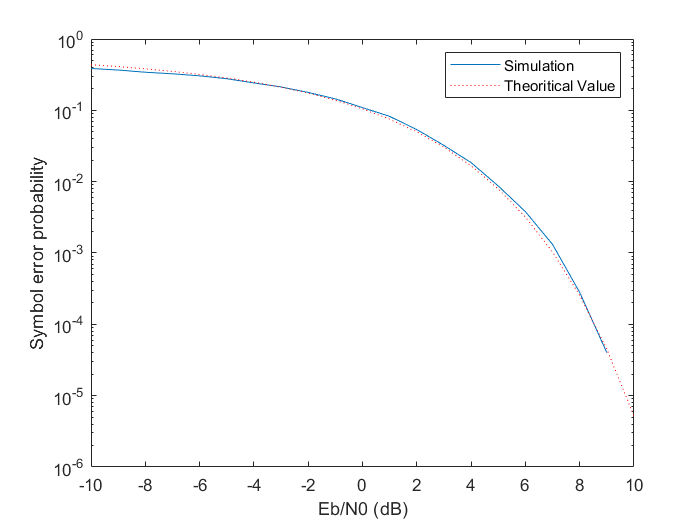

semilogy(snrdb,ber_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(snrdb/10); % raw SNR values
perr_th = 4/3*qfunc(sqrt(2*snro)); % theoretical error
semilogy(snrdb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;

### QPSK Modulation (with Gray labelling)

% modulating message symbol array
% 00 mapped to exp(pi/4*i)
% 01 mapped to exp(3pi/4*i)
% 10 mapped to exp(7pi/4*i)
% 11 mapped to exp(5pi/4*i)
mod=zeros(nsym/2,1);
for i=1:2:nsym
    m2=10*m(i)+m(i+1); % temporary variable used for mapping
    mod((i+1)/2)=(m2==0)*exp(1i*pi/4)+(m2==1)*exp(1i*3*pi/4)+ ...
                 (m2==10)*exp(1i*7*pi/4)+(m2==11)*exp(1i*5*pi/4);
end

### Adding AWGN and Demodulating (with Gray labelling)

% declaring estimated Bit Error Rate (BER) array
ber_est = zeros(nsnrdb,1);
for k=1:nsnrdb
% calculating sigma from noise power
sigma=sqrt(1/(4*(10^(snrdb(k)/10))));
% adding AWGN to modulated signal
received = mod + sigma*randn(nsym/2,1)+1i*sigma*randn(nsym/2,1);
% DECLARING 2 ARRAYS USEFUL FOR ERROR CALCULATION
% creating array of  size (nsym/2,4) with 
% each row as constellation array
arr1=ones(nsym/2,4).*qpskcon;
% creating array size (nsym/2,4) with 
% each column as received signal array
arr2=ones(nsym/2,4).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3 or 4) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx=1 is bit=00
% idx=2 is bit=01
% idx=3 is bit=11
% idx=4 is bit=10
demod=zeros(nsym,1);
for i=1:length(idx)
    if idx(i)==1
        demod(2*i-1:2*i)=[0 0];
    elseif idx(i)==2
        demod(2*i-1:2*i)=[0 1];
    elseif idx(i)==3
        demod(2*i-1:2*i)=[1 1];
    elseif idx(i)==4
        demod(2*i-1:2*i)=[1 0];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
ber_est(k)=sum(demod~=m)/nsym;
end

### Plotting Graphs (with Gray labelling)

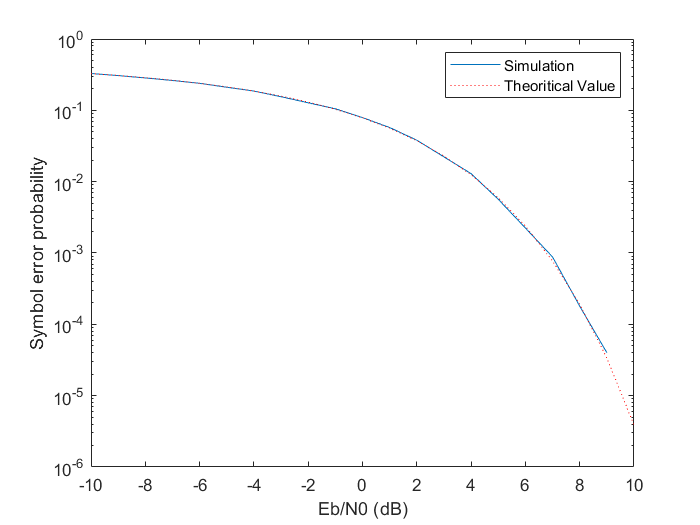

semilogy(snrdb,ber_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(snrdb/10); % raw SNR values
perr_th = qfunc(sqrt(2*snro)); % theoretical error
semilogy(snrdb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;

X=[1 2 3 4 5 6 7 8 9 10 11 12];
Y=reshape(X(:),4,[])'

Y =      1     2     3     4
     5     6     7     8
     9    10    11    12
